format shortg

# Kapittel 2.1

## E2 

## 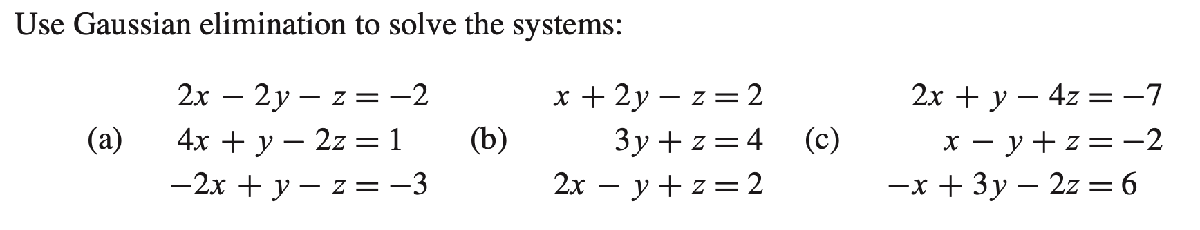

### b)

setter ligningene inn i en matrise:


$$\begin{array}{l}
1x+2y-1z=2\\
0x+3y+1z=4\\
2x-1y+1z=2
\end{array}$$
 
$$\Rightarrow \left\lbrack \begin{array}{cccc}
1 & 2 & -1 & 2\\
0 & 3 & 1 & 4\\
2 & -1 & 1 & 2
\end{array}\right\rbrack$$


Gauss-eliminerer:


$$\left\lbrack \begin{array}{cccc}
1 & 2 & -1 & 2\\
0 & 3 & 1 & 4\\
2 & -1 & 1 & 2
\end{array}\right\rbrack \;\Rightarrow \left\lbrack \begin{array}{cccc}
1 & 2 & -1 & 2\\
0 & 3 & 1 & 4\\
0 & -5 & 3 & -2
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{cccc}
1 & 2 & -1 & 2\\
0 & 3 & 1 & 4\\
0 & -15 & 9 & -6
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{cccc}
1 & 2 & -1 & 2\\
0 & 3 & 1 & 4\\
0 & 0 & 14 & 14
\end{array}\right\rbrack$$


Setter tilbake verdiene i likningene og får:


$$\begin{array}{l}
14z=14\\
z=1
\end{array}$$

$$\;\Rightarrow \;$$

$$\begin{array}{l}
3y+\left(1\right)=4\\
3y=3\\
y=1
\end{array}$$

$$\;\Rightarrow \;$$

$$\begin{array}{l}
x+2\left(1\right)-\left(1\right)=2\\
x=2-2+1\\
x=1
\end{array}$$
 
$$\Rightarrow \left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}=1\\
\mathit{\mathbf{y}}=1\\
\mathit{\mathbf{z}}=1
\end{array}\right\rbrack$$


## E6

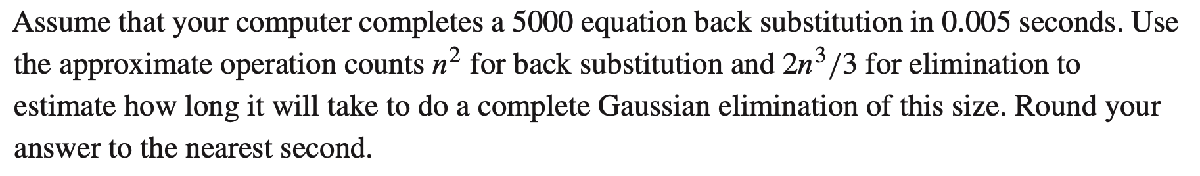

System med $5000$ likninger

n=5000;

tilbakesubstitusjon på 0.005s betyr at $n^2 *t=0\ldotp 005s$ hvor $n^2$er antall operasjoner og $t$er tiden per operasjon:

tid_per_operasjon=0.005/n^2;                
fprintf("%.10f sekunder per operasjon", tid_per_operasjon)

0.0000000002 sekunder per operasjon

for eliminisjanonen med $2\frac{n^3 }{3}$ operasjoner får vi en tid på:

ans = ((2*n^3)/3)*tid_per_operasjon;        
fprintf("%.2f sekunder",ans)

16.67 sekunder

## CP1

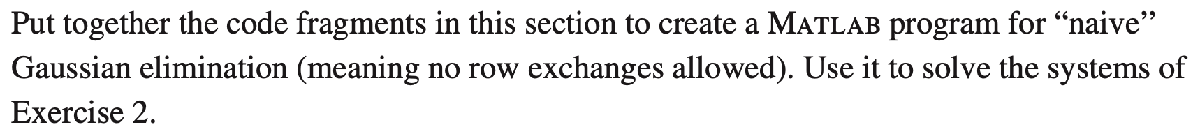

Sjekker svar av funksjonene ved å bruke oppgave E2b

Ab = [[1  2 -1  2];
     [0  3  1  4];
     [2 -1  1  2]];
 
X = tilbakesubstitusjon(gausselim(Ab));
fprintf("x = %d\ny = %d\nz = %d",X(1,1),X(2,1),X(3,1))

x = 1
y = 1
z = 1

## CP2

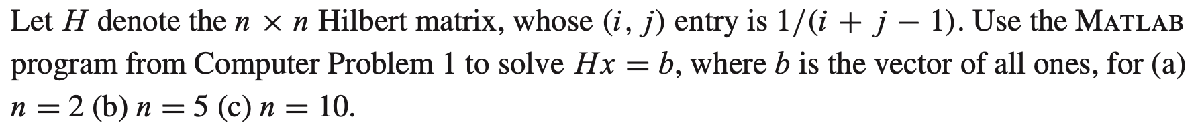

H2 = hilbert(2)

H2 =            -2
            6


H5 = hilbert(5)

H5 =             5
         -120
          630
        -1120
          630


H10 = hilbert(10)

H10 =       -9.9974
       989.77
       -23755
    2.402e+05
   -1.261e+06
   3.7832e+06
  -6.7258e+06
   7.0004e+06
  -3.9377e+06
   9.2367e+05


# Kapittel 2.2

## E2 

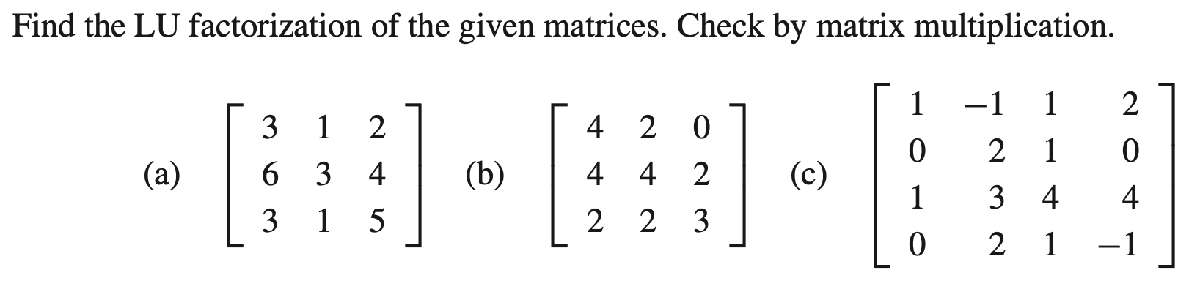

### b)

        A                                                            U                            L

$\left\lbrack \begin{array}{ccc}
4 & 2 & 0\\
4 & 4 & 2\\
2 & 2 & 3
\end{array}\right\rbrack$$\textrm{trekker}\;\textrm{fra}\;1*\textrm{rad1}\;\textrm{på}\;\textrm{rad2}\Rightarrow$$\left\lbrack \begin{array}{ccc}
4 & 2 & 0\\
0 & 2 & 2\\
2 & 2 & 3
\end{array}\right\rbrack \textrm{og}\;L=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
1 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$         lagret i én matrise: $\left\lbrack \begin{array}{ccc}
4 & 2 & 0\\
1 & 2 & 2\\
2 & 2 & 3
\end{array}\right\rbrack$

$\left\lbrack \begin{array}{ccc}
4 & 2 & 0\\
0 & 2 & 2\\
2 & 2 & 3
\end{array}\right\rbrack$$\textrm{trekker}\;\textrm{fra}\;\frac{1}{2}*\textrm{rad1}\;\textrm{på}\;\textrm{rad}\;3\Rightarrow$$\left\lbrack \begin{array}{ccc}
4 & 2 & 0\\
0 & 2 & 2\\
0 & 1 & 3
\end{array}\right\rbrack \textrm{og}\;L=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
1 & 1 & 0\\
\frac{1}{2} & 0 & 1
\end{array}\right\rbrack \;$        lagret i én matrise: $\left\lbrack \begin{array}{ccc}
4 & 2 & 0\\
1 & 2 & 2\\
\frac{1}{2} & 1 & 3
\end{array}\right\rbrack$

$\left\lbrack \begin{array}{ccc}
4 & 2 & 0\\
0 & 2 & 2\\
0 & 1 & 3
\end{array}\right\rbrack$$\textrm{trekker}\;\textrm{fra}\;\frac{1}{2}*\textrm{rad2}\;\textrm{på}\;\textrm{rad}\;3\Rightarrow$$\left\lbrack \begin{array}{ccc}
4 & 2 & 0\\
0 & 2 & 2\\
0 & 0 & 2
\end{array}\right\rbrack \textrm{og}\;L=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
1 & 1 & 0\\
\frac{1}{2} & \frac{1}{2} & 1
\end{array}\right\rbrack \;$        lagret i én matrise: $\left\lbrack \begin{array}{ccc}
4 & 2 & 0\\
1 & 2 & 2\\
\frac{1}{2} & \frac{1}{2} & 2
\end{array}\right\rbrack$

altså har vi $L=\;$$\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
1 & 1 & 0\\
\frac{1}{2} & \frac{1}{2} & 1
\end{array}\right\rbrack$

sjekker om $\textrm{LU}=A\;$stemmer:


$$\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
1 & 1 & 0\\
\frac{1}{2} & \frac{1}{2} & 1
\end{array}\right\rbrack *\left\lbrack \begin{array}{ccc}
4 & 2 & 0\\
0 & 2 & 2\\
0 & 0 & 2
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1*4 & 1*2 & 1*0\\
1*4+1*0 & 1*2+1*2 & 1*0+1*2\\
\frac{4}{2}+\frac{0}{2}+1*0 & \frac{2}{2}+\frac{2}{2}+1*0 & \frac{0}{2}+\frac{2}{2}+1*1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
4 & 2 & 0\\
4 & 4 & 2\\
2 & 2 & 3
\end{array}\right\rbrack =A$$


## E8

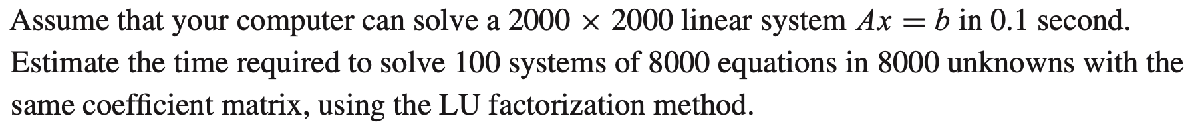

Med 2000 liknginger: 

n=2000;

$\textrm{Ax}=b$ tilsvarer gauss-eliminiasjon med $2\frac{n^3 }{3}$ operasjoner, disse blir gjort på 0.1 sekund og vi får:

tid_per_operasjon = 0.1/((2*n^3)/3)

tid_per_operasjon =     1.875e-11


Vi skal bruke samme maskin til å løse 100 likningsystemer med 8000 likninger hver:

k = 100;
n = 8000;

Siden alle likningsystemene har samme koeffisientmatrise trenger vi kun gausseliminere én gang, for deretter å utføre tilbakesubstitusjonen k ganger.

ant_operasjoner = (2*n^3)/3 + k*2*n^2

ant_operasjoner =    3.5413e+11


da får vi den totale tiden for alle likningsystemene:

tid = ant_operasjoner * tid_per_operasjon;
fprintf("total tid: %.2f sekunder", tid)

total tid: 6.64 sekunder

## CP1

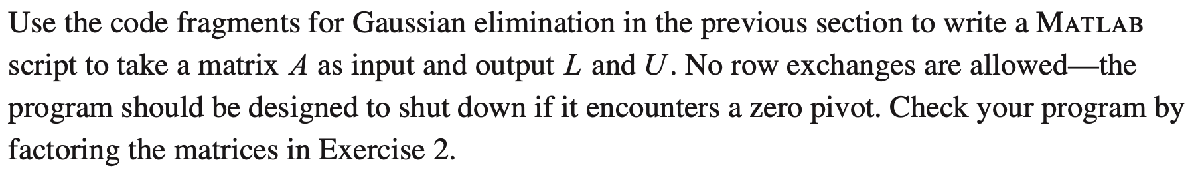

Sjekker med svarene fra oppgave E2b $A=\left\lbrack \begin{array}{ccc}
4 & 2 & 0\\
4 & 4 & 2\\
2 & 2 & 3
\end{array}\right\rbrack \textrm{gir}:\;\;L=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
1 & 1 & 0\\
\frac{1}{2} & \frac{1}{2} & 1
\end{array}\right\rbrack \;\textrm{og}\;U=\left\lbrack \begin{array}{ccc}
4 & 2 & 0\\
0 & 2 & 2\\
0 & 0 & 2
\end{array}\right\rbrack$

A = [[4 2 0];
     [4 4 2];
     [2 2 3]];
 
[L, U] = LU_faktoriser(A)

L =             1            0            0
            1            1            0
          0.5          0.5            1


U =      4     2     0
     0     2     2
     0     0     2


## CP2

Sjekker mot E4a

A = [[3 1 2];
     [6 3 4];
     [3 1 5]];
 
b = [0 1 3]; 

x = LU_tilbakesubstitusjon(A, b)

L =      1     0     0
     2     1     0
     1     0     1


U =      3     1     2
     0     1     0
     0     0     3


x =     -1
     1
     1


Sjekker mot E4b

A = [[4 2 0];
     [4 4 2];
     [2 2 3]];
 
b = [2 4 6]; 

x = LU_tilbakesubstitusjon(A, b)

L =             1            0            0
            1            1            0
          0.5          0.5            1


U =      4     2     0
     0     2     2
     0     0     2


x =      1
    -1
     2


# Kapittel 2.3

## E2 

### 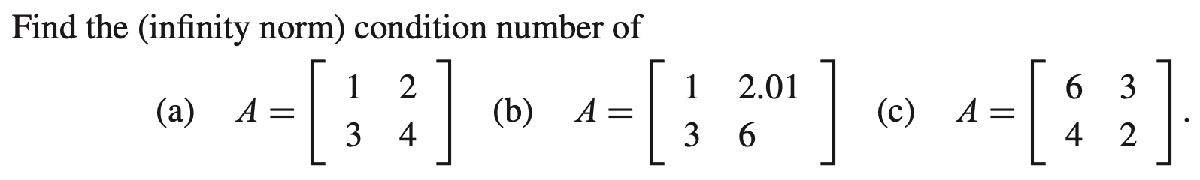

### b)

$A\;\;\;\;\;\;\;\;\;\;=\left\lbrack \begin{array}{cc}
1 & 2\ldotp 01\\
3 & 6
\end{array}\right\rbrack$     finner den inverse til A $\Rightarrow$    $A^{-1} =\frac{1}{1*6-2\ldotp 01*3}\left\lbrack \begin{array}{cc}
6 & -2\ldotp 01\\
-3 & 1
\end{array}\right\rbrack =\frac{1}{-0\ldotp 03}\left\lbrack \begin{array}{cc}
6 & -2\ldotp 01\\
-3 & 1
\end{array}\right\rbrack$


$$\begin{array}{l}
\textrm{cond}\left(A\right)=\left|\left|A\right|\right|*\left|\left|A^{-1} \right|\right|\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\max \left(1+2\ldotp 01,3+6\right)*\frac{\max \left(6+2\ldotp 01,\;3+1\right)}{0\ldotp 03}
\end{array}$$


condA = abs(max((1+2.01),(3+6))*max((6+2.01),(3+1))/-0.03)

condA =         2403


## E13 

## 

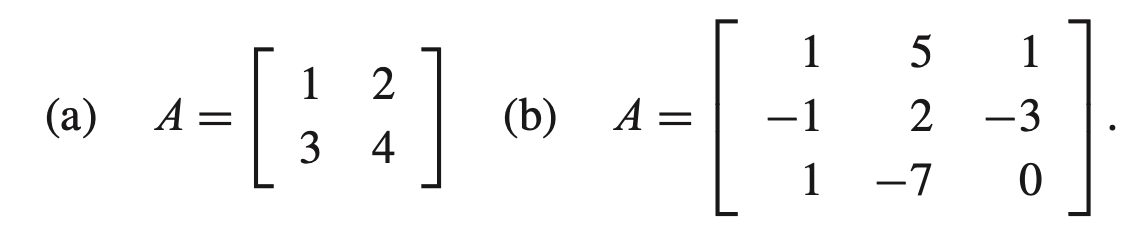

### a)


$$A=\left\lbrack \begin{array}{cc}
\;1 & 2\\
3 & 4
\end{array}\right\rbrack$$


vi har at ${\left|\left|A\right|\right|}_{\infty } =\frac{{\left|\left|A*x\right|\right|}_{\infty } }{{\left|\left|x\right|\right|}_{\infty } }$      og ${\left|\left|A\right|\right|}_{\infty } =\max \left(1+2,3+4\right)=7$

vi ønsker altså å ha $x$ slik at $\frac{{\left|\left|A*x\right|\right|}_{\infty } }{{\left|\left|x\right|\right|}_{\infty } }=7=\frac{7}{1}$

ser at dersom vi har $x=\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$ vil ${\left|\left|x\right|\right|}_{\infty } =\max \left(1,\;1\right)=1$ og


$$A*x=$$

$$\left\lbrack \begin{array}{cc}
1 & 2\\
3 & 4
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
3\\
7
\end{array}\right\rbrack \;\Rightarrow \;{\left|\left|A*x\right|\right|}_{\infty } ={\left|\left|\left\lbrack \begin{array}{c}
3\\
7
\end{array}\right\rbrack \right|\right|}_{\infty } =\max \left(3,\;7\right)=7$$


altså får vi ${\left|\left|A\right|\right|}_{\infty } =\frac{{\left|\left|A*x\right|\right|}_{\infty } }{{\left|\left|x\right|\right|}_{\infty } }=\frac{7}{1}=7$ med $x={\left\lbrack 1\;\;\;1\right\rbrack }^T$

## E14 

### 

### a)


$$A=\left\lbrack \begin{array}{cc}
1 & 2\\
3 & 4
\end{array}\right\rbrack$$


vi har at ${\left|\left|A\right|\right|}_1 =\frac{{\left|\left|A*x\right|\right|}_1 }{{\left|\left|x\right|\right|}_1 }$      og ${\left|\left|A\right|\right|}_1 =\max \left(1+3,\;2+4\right)=6$

vi ønsker altså å ha $x$ slik at $\frac{{\left|\left|A*x\right|\right|}_1 }{{\left|\left|x\right|\right|}_1 }=6=\frac{6}{1}$

ser at dersom vi har $x=\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$ vil ${\left|\left|x\right|\right|}_1 =\;0\;+\;1=1$ og


$$A*x=$$

$$\left\lbrack \begin{array}{cc}
1 & 2\\
3 & 4
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
4
\end{array}\right\rbrack \;\Rightarrow \;{\left|\left|A*x\right|\right|}_1 ={\left|\left|\left\lbrack \begin{array}{c}
2\\
4
\end{array}\right\rbrack \right|\right|}_{\infty } =2\;+\;4=6$$


altså får vi ${\left|\left|A\right|\right|}_1 =\frac{{\left|\left|A*x\right|\right|}_1 }{{\left|\left|x\right|\right|}_1 }=\frac{6}{1}=6$ med $\mathit{\mathbf{x}}={\left\lbrack 0\;\;\;1\right\rbrack }^{\mathit{\mathbf{T}}}$

## CP6

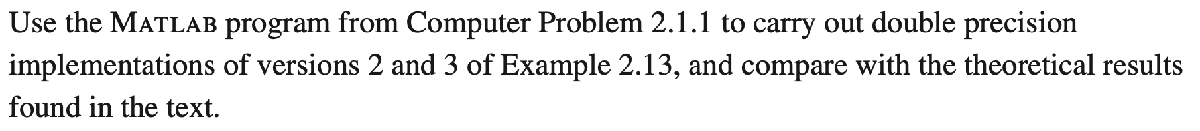

Prøver først med vanlig pivotering

A = [[ 10^(-20)   1];
     [    1       2]];
b = [1 4];
 
x = LU_tilbakesubstitusjon(A, b)

L =             1            0
        1e+20            1


U =         1e-20            1
   1.1102e-16       -1e+20


x =      0
     1


ser at vi får $x=\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$som ikke stemmer, prøver derfor på nytt med pivotering: 

A = [[    1      2];
     [ 10^(-20)  1]];
b = [4 1];
 
x = LU_tilbakesubstitusjon(A, b)

L =             1            0
        1e-20            1


U =      1     2
     0     1


x =      2
     1


Her unngår vi swamping og får det korrekte svaret $x=\left\lbrack \begin{array}{c}
2\\
1
\end{array}\right\rbrack$

# Kapittel 2.4

## E2 

## 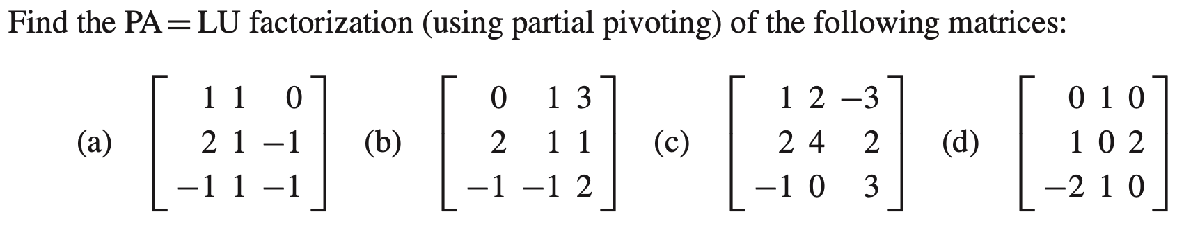

### c)

har matrisen: $A=\left\lbrack \begin{array}{ccc}
1 & 2 & -3\\
2 & 4 & 2\\
-1 & 0 & 3
\end{array}\right\rbrack$bytter plass på 1 og 2

$\left\lbrack \begin{array}{ccc}
2 & 4 & 2\\
1 & 2 & -3\\
-1 & 0 & 3
\end{array}\right\rbrack$ganger med $-\frac{1}{2}$ og $\frac{1}{2}$=> $\left\lbrack \begin{array}{ccc}
2 & 4 & 2\\
\left(-1/2\right) & 0 & -4\\
\left(1/2\right) & 2 & 4
\end{array}\right\rbrack$

$\left\lbrack \begin{array}{ccc}
2 & 4 & 2\\
1 & 2 & -3\\
-1 & 0 & 3
\end{array}\right\rbrack$ganger med $-\frac{1}{2}$ og $\frac{1}{2}$=> $\left\lbrack \begin{array}{ccc}
2 & 4 & 2\\
\left(1/2\right) & 0 & -4\\
\left(-1/2\right) & 2 & 4
\end{array}\right\rbrack$

$\left\lbrack \begin{array}{ccc}
2 & 4 & 2\\
\left(1/2\right) & 0 & -4\\
\left(-1/2\right) & 2 & 4
\end{array}\right\rbrack$bytter plass på rad 2 og 3 => $\left\lbrack \begin{array}{ccc}
2 & 4 & 2\\
\left(-1/2\right) & 2 & 4\\
\left(1/2\right) & \left(0\right) & -4
\end{array}\right\rbrack$

da er vi ferdig og vi får:

  
$$\;\;\;\;\;\;\;\;P\;\;\;\;\;\;\;\;\;*\;\;\;\;\;\;\;A\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;L\;\;\;\;\;\;\;\;\;\;\;*\;\;\;\;\;\;\;\;\;U$$


$\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
1 & 0 & 0
\end{array}\right\rbrack$$\left\lbrack \begin{array}{ccc}
1 & 2 & -3\\
2 & 4 & 2\\
-1 & 0 & 3
\end{array}\right\rbrack$   =  $\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
-1/2 & 1 & 0\\
1/2 & 0 & 1
\end{array}\right\rbrack$$\left\lbrack \begin{array}{ccc}
2 & 4 & 2\\
0 & 2 & 4\\
0 & 0 & -4
\end{array}\right\rbrack$

## E4

## 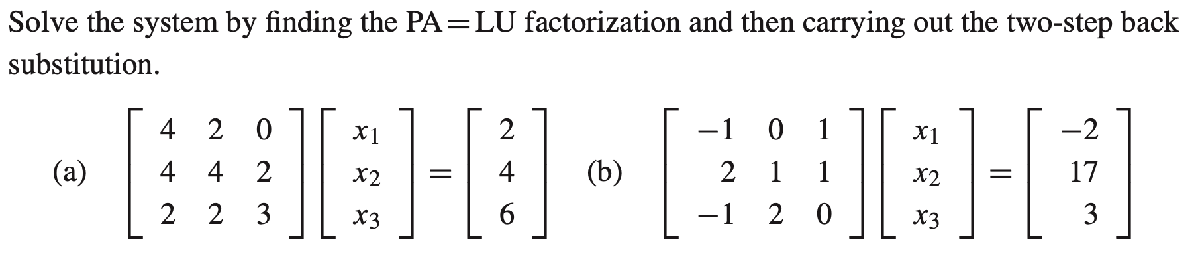 

### b)

har matrisen: $A=\left\lbrack \begin{array}{ccc}
-1 & 0 & 1\\
2 & 1 & 1\\
-1 & 2 & 0
\end{array}\right\rbrack$,$x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack$og $b=\left\lbrack \begin{array}{c}
-2\\
17\\
3
\end{array}\right\rbrack$

finner først $\textrm{PA}=\textrm{LU}$ for A

$\left\lbrack \begin{array}{ccc}
-1 & 0 & 1\\
2 & 1 & 1\\
-1 & 2 & 0
\end{array}\right\rbrack$bytter plass på rad 1 og 2                             $\;\left\lbrack \begin{array}{ccc}
2 & 1 & 1\\
-1 & 0 & 1\\
-1 & 2 & 0
\end{array}\right\rbrack$

$\left\lbrack \begin{array}{ccc}
2 & 1 & 1\\
-1 & 0 & 1\\
-1 & 2 & 0
\end{array}\right\rbrack$ganger rad1 med 1/2 mot rad2 og 3        => $\;\left\lbrack \begin{array}{ccc}
2 & 1 & 1\\
\left(-1/2\right) & 1/2 & 3/2\\
\left(-1/2\right) & 5/2 & 1/2
\end{array}\right\rbrack$

$\left\lbrack \begin{array}{ccc}
2 & 1 & 1\\
\left(-1/2\right) & 1/2 & 3/2\\
\left(-1/2\right) & 5/2 & 1/2
\end{array}\right\rbrack$bytter plass på rad 2 og 3          => $\;\left\lbrack \begin{array}{ccc}
2 & 1 & 1\\
\left(-1/2\right) & 5/2 & 1/2\\
\left(-1/2\right) & 1/2 & 3/2
\end{array}\right\rbrack$

$\left\lbrack \begin{array}{ccc}
2 & 1 & 1\\
\left(-1/2\right) & 5/2 & 1/2\\
\left(-1/2\right) & 1/2 & 3/2
\end{array}\right\rbrack$ganger rad2 med -1/5 mot  rad3 => $\left\lbrack \begin{array}{ccc}
2 & 1 & 1\\
\left(-1/2\right) & 5/2 & 1/2\\
\left(-1/2\right) & \left(1/5\right) & 7/5
\end{array}\right\rbrack$

Da har vi funnet:

  
$$\;\;\;\;\;\;\;\;P\;\;\;\;\;\;\;\;\;*\;\;\;\;\;\;\;A\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;L\;\;\;\;\;\;\;\;\;\;\;*\;\;\;\;\;\;\;\;\;U$$


$\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
1 & 0 & 0
\end{array}\right\rbrack$$\left\lbrack \begin{array}{ccc}
-1 & 0 & 1\\
2 & 1 & 1\\
-1 & 2 & 0
\end{array}\right\rbrack$     =  $\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
-1/2 & 1 & 0\\
-1/2 & 1/5 & 1
\end{array}\right\rbrack$$\left\lbrack \begin{array}{ccc}
2 & 1 & 1\\
0 & 5/2 & 1/2\\
0 & 0 & 7/5
\end{array}\right\rbrack$

løser så først $\textrm{Lc}=\textrm{Pb}$


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;L\;\;\;\;\;\;\;\;\;\;\;\;*\;\;c\;\;\;\;\;\;\;\;\;=\;\;\;\;\;\;\;\;\;\;\;P\;\;\;\;\;\;\;\;*\;\;b$$


$\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
-1/2 & 1 & 0\\
-1/2 & 1/5 & 1
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
c_1 \\
c_2 \\
c_3 
\end{array}\right\rbrack$     =  $\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
1 & 0 & 0
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
-2\\
17\\
3
\end{array}\right\rbrack$

$\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
-1/2 & 1 & 0\\
-1/2 & 1/5 & 1
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
c_1 \\
c_2 \\
c_3 
\end{array}\right\rbrack$     =   $\left\lbrack \begin{array}{c}
17\\
3\\
-2
\end{array}\right\rbrack$

dette gir oss tre likninger:


$$\begin{array}{l}
1*c_1 =17\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow c_1 =17\\
\left(-\frac{1}{2}*c_1 \right)+\left(1*c_2 \right)=3\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow c_2 =3-\left(-\frac{1}{2}*c_1 \right)\\
\left(-\frac{1}{2}*c_1 \right)+\left(\frac{1}{5}*c_2 \right)+\left(1*c_3 \right)=-2\;\;\;\;\;\;\Rightarrow c_3 =-2-\left(-\frac{c_1 }{2}\right)-\left(\frac{c_2 }{5}\right)
\end{array}$$


altså:

c1 = 17;   
c2 = 3-(-1/2*c1);         %23/2
c3 = -2-(-c1/2)-(c2/5);   %21/5
c  = [c1 c2 c3]'

c =            17
         11.5
          4.2


deretter løser vi $\textrm{Ux}=c$


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;U\;\;\;\;\;\;\;\;\;\;\;\;*\;x\;\;\;\;\;\;=\;\;\;\;\;\;\;\;\;\;c$$


$\left\lbrack \begin{array}{ccc}
2 & 1 & 1\\
0 & 5/2 & 1/2\\
0 & 0 & 7/5
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack$     =  $\;\;\;\;\left\lbrack \begin{array}{c}
c_1 \\
c_2 \\
c_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
17\\
23/2\\
21/5
\end{array}\right\rbrack$

dette gir oss tre nye likninger:


$$\begin{array}{l}
\frac{7}{5}*x_3 =c_3 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow x_3 =\frac{c_3 }{7/5}\\
\left(\frac{5}{2}*x_2 \right)+\left(\frac{1}{2}*x_3 \right)=c_2 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow x_2 =\frac{c_2 -\left(x_3 /2\right)}{5/2}\\
\left(2*x_1 \right)+\left(1*x_2 \right)+\left(1*x_3 \right)=c_1 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow x_1 =\frac{c_1 -\left(x_2 \right)-\left(x_3 \right)}{2}
\end{array}$$


altså:

x3 = c3/(7/5);
x2 = (c2-x3/2)/(5/2);
x1 = (c1-x2-x3)/2;
x  = [x1 x2 x3]'

x =             5
            4
            3


# Kapittel 2.5

## E1 

### 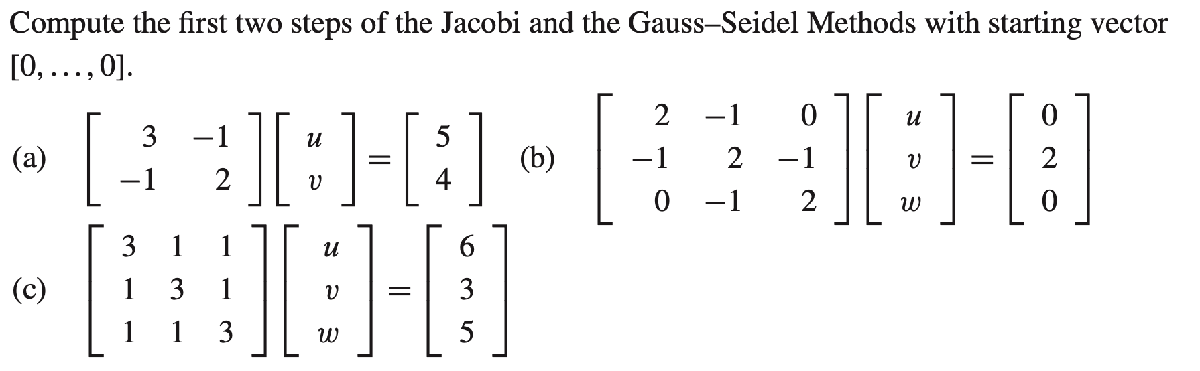

### b)

har $\left\lbrack \begin{array}{ccc}
2 & -1 & 0\\
-1 & 2 & -1\\
0 & -1 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
2\\
0
\end{array}\right\rbrack$og skal bruke startvektor $\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$

#### Jacobi - bruker forrige verdier av u,vog w:


$$\begin{array}{l}
2u-v=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow \;\;u_n =\frac{v_{n-1} }{2}\\
-u+2v-w=2\;\;\;\;\;\;\;\;\;\;\;\Rightarrow \;v_n =\frac{2+u_{n-1} +w_{n-1} }{2}\\
-v+2w=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow w_n =\frac{v_{n-1} }{2}\;
\end{array}$$


starter med $\left\lbrack \begin{array}{c}
u_0 \\
v_0 \\
w_0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$

da får vi: 


$$\left\lbrack \begin{array}{c}
u_1 \\
v_1 \\
w_1 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v_0 /2\\
\left(2+u_0 +w_0 \right)/2\\
v_0 /2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0/2\\
\left(2+0+0\right)/2\\
0/2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
1\\
0
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
u_2 \\
v_2 \\
w_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v_1 /2\\
\left(2+u_1 +w_1 \right)/2\\
v_1 /2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1/2\\
\left(2+0+0\right)/2\\
1/2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1/2\\
1\\
1/2
\end{array}\right\rbrack$$


#### Gauss-Seidel - bruker nye verdier av u,v og w med en gang vi finner dem:


$$\begin{array}{l}
\;u_n =\frac{v_{n-1} }{2}\\
v_n =\frac{2+u_n +w_{n-1} }{2}\\
w_n =\frac{v_n }{2}\;
\end{array}$$


starter med $\left\lbrack \begin{array}{c}
u_0 \\
v_0 \\
w_0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$

da får vi: 


$$\left\lbrack \begin{array}{c}
u_1 \\
v_1 \\
w_1 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v_0 /2\\
\left(2+u_1 +w_0 \right)/2\\
v_1 /2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0/2\\
\left(2+0+0\right)/2\\
1/2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
1\\
1/2
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
u_2 \\
v_2 \\
w_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v_1 /2\\
\left(2+u_2 +w_1 \right)/2\\
v_2 /2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1/2\\
\left(2+1/2+1/2\right)/2\\
\left(3/2\right)/2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1/2\\
3/2\\
3/4
\end{array}\right\rbrack$$


## E2 

### 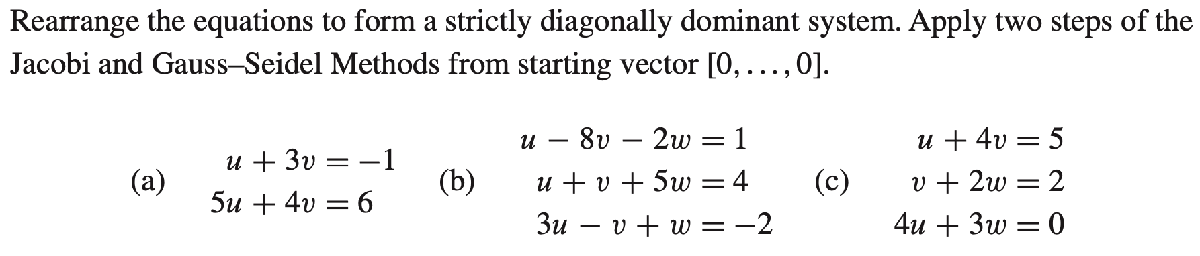

### c)

vi får likningsystemet  $\begin{array}{l}
u+4v=5\\
v+2w=2\\
4u+3w=0
\end{array}$$\Rightarrow \left\lbrack \begin{array}{cccc}
1 & 4 & 0 & 5\\
0 & 1 & 2 & 2\\
4 & 0 & 3 & 0
\end{array}\right\rbrack$

først må vi arrangere matrisen slik at den blir diagonal-dominant:


$$\left\lbrack \begin{array}{cccc}
1 & 4 & 0 & 5\\
0 & 1 & 2 & 2\\
4 & 0 & 3 & 0
\end{array}\right\rbrack *\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
1 & 0 & 0\\
0 & 1 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
4 & 0 & 3 & 0\\
1 & 4 & 0 & 5\\
0 & 1 & 2 & 2
\end{array}\right\rbrack$$


#### Jacobi 


$$\begin{array}{l}
u_n =\frac{{-3*w}_{n-1} }{4}\\
\;v_n =\frac{5-u_{n-1} }{4}\\
w_n =\frac{{2-v}_{n-1} }{2}\;
\end{array}$$


starter med $\left\lbrack \begin{array}{c}
u_0 \\
v_0 \\
w_0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$

da får vi: 


$$\left\lbrack \begin{array}{c}
u_1 \\
v_1 \\
w_1 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(-3{*w}_0 \right)/4\\
\left(5-u_0 \right)/4\\
\left({2-v}_0 \right)/2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(-3*0\right)/4\\
\left(5-0\right)/4\\
\left(2-0\right)/2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
5/4\\
1
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
u_2 \\
v_2 \\
w_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(-3{*w}_1 \right)/4\\
\left(5-u_1 \right)/4\\
\left({2-v}_1 \right)/2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(-3*1\right)/4\\
\left(5-0\right)/4\\
\left(2-5/4\right)/2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-3/4\\
5/4\\
3/8
\end{array}\right\rbrack$$


#### Gauss-Seidel 


$$\begin{array}{l}
u_n =\frac{{-3*w}_{n-1} }{4}\\
\;v_n =\frac{5-u_n }{4}\\
w_n =\frac{{2-v}_n }{2}\;
\end{array}$$


starter med $\left\lbrack \begin{array}{c}
u_0 \\
v_0 \\
w_0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$

da får vi: 


$$\left\lbrack \begin{array}{c}
u_1 \\
v_1 \\
w_1 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(-3{*w}_0 \right)/4\\
\left(5-u_1 \right)/4\\
\left({2-v}_1 \right)/2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(-3*0\right)/4\\
\left(5-0\right)/4\\
\left(2-5/4\right)/2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
5/4\\
3/8
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
u_2 \\
v_2 \\
w_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(-3{*w}_1 \right)/4\\
\left(5-u_2 \right)/4\\
\left(2-v_2 \right)/2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(-3*3/8\right)/4\\
\left(5-\left(-9/32\right)\right)/4\\
\left(2-169/128\right)/2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-9/32\\
169/128\\
87/256
\end{array}\right\rbrack$$


## CP1

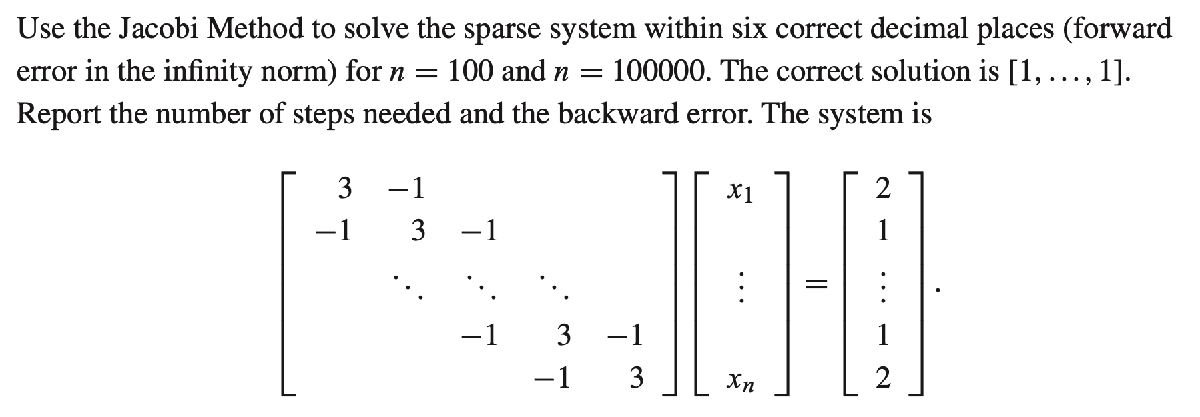

[steg fremoverfeil bakoverfeil] = jacobi(100)

steg =     36


fremoverfeil =    4.5784e-07


bakoverfeil =    4.5785e-07


[steg fremoverfeil bakoverfeil] = jacobi(100000)

steg =     36


fremoverfeil =    4.5784e-07


bakoverfeil =    4.5785e-07
